clear all
load total_biomass.txt
load ForVaMeintenance.txt
load AcVsMeintenance.txt
load CO2VsMeintenance.txt

x = categorical(["0" "4" "8" "16"]);
x = reordercats(x,{'0' '4' '8' '16'});

%ybio=total_biomass(:,2)
%bar(ybio)
%hold on
%barchart(1,:)=transpose(CO2VsMeintenance(:,2))
barchart(1,:)=transpose(ForVaMeintenance(:,2))

barchart =     0.0014    0.0015    0.0015    0.0017


barchart(2,:)=transpose(AcVsMeintenance(:,2))

barchart =     0.0014    0.0015    0.0015    0.0017
    0.0001    0.0001    0.0001    0.0002


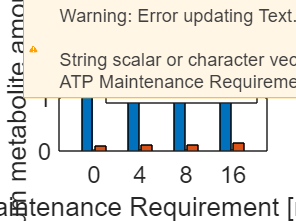

ax =   Axes with properties:

             XLim: [0    16]
             YLim: [0 0.0022]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


hBar=bar(x,transpose(barchart));
%set(gca,'YScale','log')
ylim([0 2.2e-3])
xlabel('ATP Maintenance Requirement [mmol/g·h]','interpreter','latex')
ylabel('Maximum metabolite amount [mmol]')
legend('Formate','Acetate')
ax=gca;
ax.FontSize=13

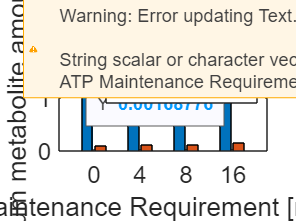

exportgraphics(gcf,'metabolites.png','Resolution', 300)

%yyaxis right
%x=0.5
%bBar=bar(x,transpose(total_biomass(:,2)),x);

%legend('CO_2','Formate','Acetate','Total biomass')